# Drone Payload Structure Design and Analysis

Team 6: Beam Arm and T-Arm Designs

% Task 1: Gather starter assumptions and load material properties

load('droneArmMaterials.mat');
g = 9.81; % gravity m/s^2
motor = 4; % number of motors
thrustMotor = 1; % thrust from 1 motor
baseMass = 1; % mass of body NOT arms
minPayload = 0.5; % minimum payload
TWratio = 2.0; % required ratio of thrust to weight


Task 2: Propose at least two drone arm designs

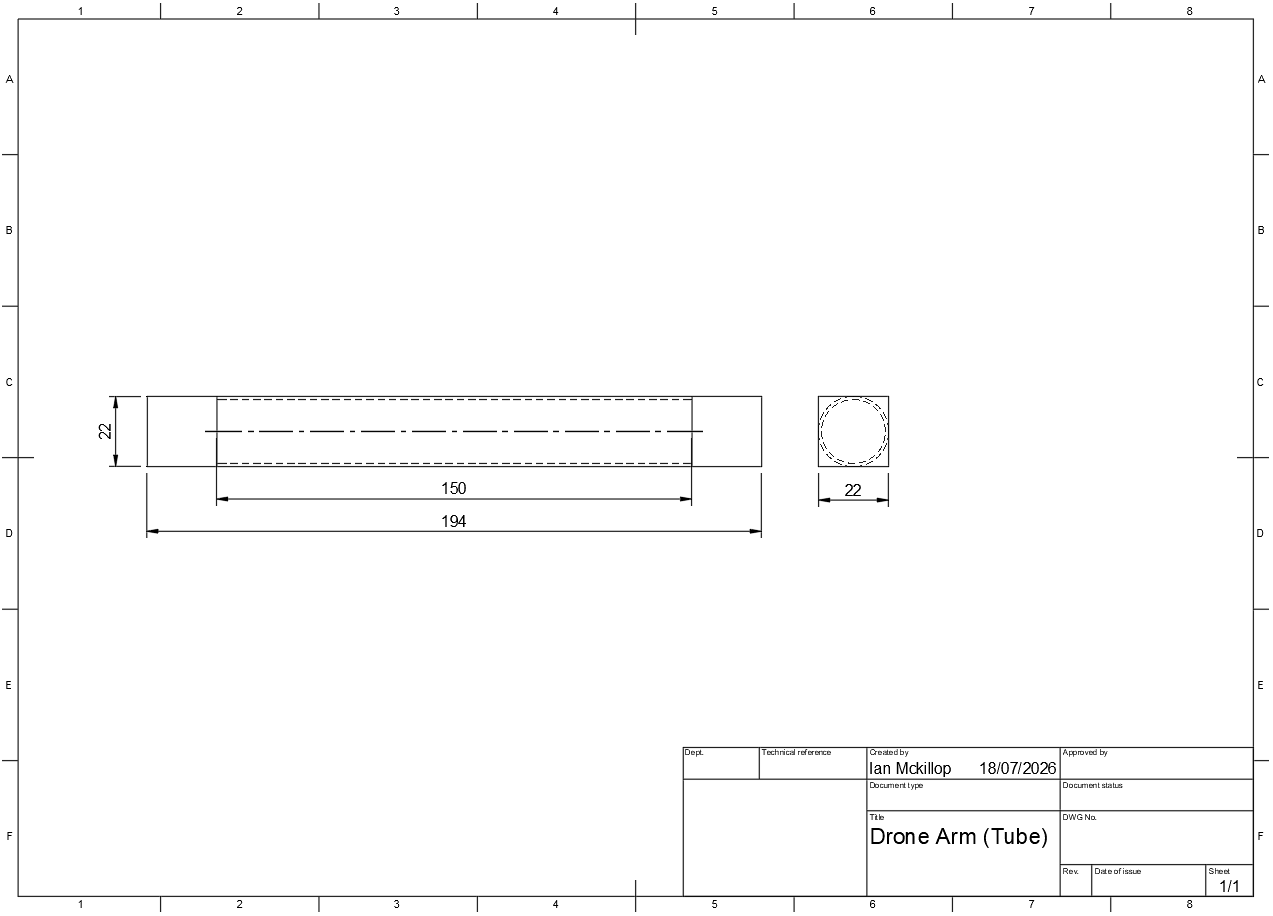

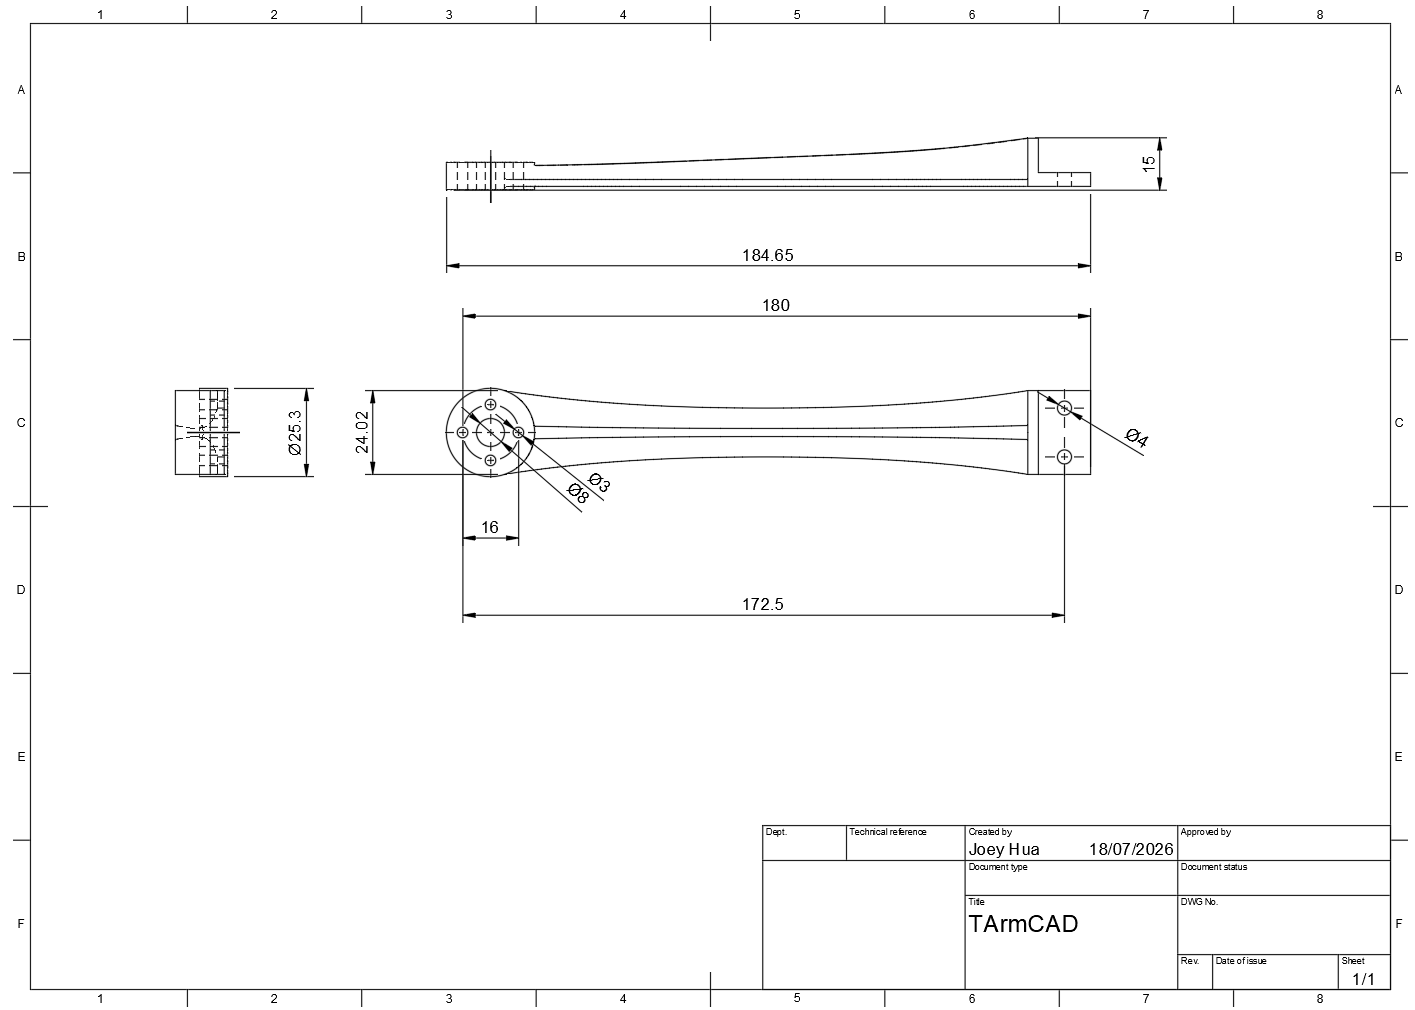

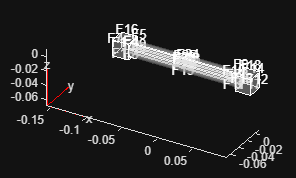

% Task 3: Thrust-to-weight analysis
% Beam Design - Thrust to Weight

volBeamArm = 0.000031192; % taken from Fusion

maxThrust = motor * thrustMotor * g;

beamResults = table();

for m = 1:numel(materials)
    mat = materials(m);

    armMass = volBeamArm * mat.rho_kg_m3;
    totalArmMass = armMass * 4;

    maxPayload = (maxThrust / (TWratio * g)) - baseMass - totalArmMass;

    meetsmin = maxPayload >= minPayload;
    
    beamResults = [beamResults; table(string(mat.name), totalArmMass, maxPayload, meetsmin, 'VariableNames', {'Material', 'ArmMass_kg', 'MaxPayload_kg' ...
        'MeetsMin'})];
end

%% T-Arm Design - Thrust to Weight
% This script will help us see the thrust to weight ratio for a truss
% drone arm design.
% Parameters:
% * Thrust must be at least 2x the weight

%Thrust Calculations for T Arm Design
volArm = 0.00001646929; %Pulled from OnShape
load('droneArmMaterials.mat');
maxThrust = motor * thrustMotor * g;

results = table();

for m = 1:numel(materials)
    mat = materials(m);

    armMass = volArm * mat.rho_kg_m3;
    totalArmMass = armMass * 4;

    maxPayload = (maxThrust / (TWratio * g)) - baseMass - totalArmMass;

    meetsmin = maxPayload >= minPayload;
    results = [results; table(string(mat.name), totalArmMass, maxPayload, meetsmin, 'VariableNames', {'Material', 'ArmMass', 'MaxPayload' ...
        'MeetsMin'})];
end

%% Task 4: Finite element analysis
%% Beam Design - FEA

tubeGm = fegeometry("Drone Arm (Tube).stl");
tubeGm = scale(tubeGm, 0.001);
tubeMd = femodel(AnalysisType="structuralStatic",Geometry=tubeGm); % create a FEA model object of the drone arm
tubeMd = generateMesh(tubeMd); % generate a mesh of the geometry
pdegplot(tubeMd,FaceLabels="on",FaceAlpha=0.3);

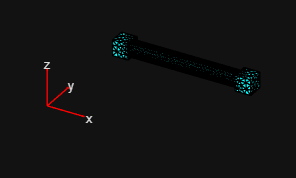

pdemesh(tubeMd); % visualize the mesh

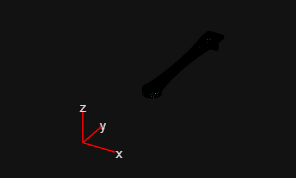


% the code below assigns the faces that connect to the drone body as
% "fixed" so they do not move. 
tubeMd.FaceBC(12) = faceBC(Constraint = 'fixed');
tubeMd.FaceBC(17) = faceBC(Constraint = 'fixed');
tubeMd.FaceBC(18) = faceBC(Constraint = 'fixed');

% the code below applies gravity and the motor thrust/weight to the drone
% arm.
netMotorForce = (1-.105)*g;
tubeMd.FaceLoad(16) = faceLoad(SurfaceTraction=[0 0 (netMotorForce / 0.000484)]);
tubeMd.CellLoad = cellLoad(Gravity=[0 0 -g]);

% the code below formats the data from the fea model and materials provided
% into a table. Type featubeResults into the command window to view the max
% stress, displacement, and factor of safety for the various materials.
featubeResults = table();

for m = 1:numel(materials)
    mat = materials(m);

    tubeMd.MaterialProperties = materialProperties(MassDensity= mat.rho_kg_m3, YoungsModulus= mat.E_Pa,... 
        PoissonsRatio= mat.nu);

    sol = solve(tubeMd); % completes the FEA (remove semicolon to view)

    maxDisplacement = max(sol.Displacement.Magnitude);
    maxStress = max(sol.VonMisesStress);
    factorOfSafety = mat.yieldStrength_Pa / maxStress;
    
    featubeResults = [featubeResults; table(string(mat.name), sol,maxDisplacement, maxStress, factorOfSafety, ...
        'VariableNames',{'Material','FEA Solution','Max Displacement','Max Stress','Factor of Safety'})];

end

%% T-Arm Design - FEA
% This section basically pulls the CAD file, sets  the analysis to static,
% and generate a mesh plus face labels visual.
tArmGm = fegeometry("TArmCAD.stl");
tArmGm = scale(tArmGm, 0.001); % converts units into meters
tArmMd = femodel(AnalysisType="structuralStatic",Geometry=tArmGm);
tArmMd = generateMesh(tArmMd); % generate a mesh of the geometry
pdemesh(tArmMd); % visualize the mesh

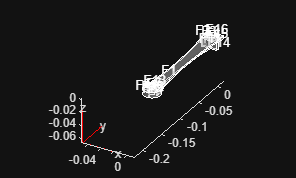

pdegplot(tArmMd,FaceLabels="on",FaceAlpha=0.3);


% This section assigns the material properties for the drone arm. We can
% loop it to see the material properties for the 6 materials we were given.
% Type featarmResults into the command window to view the max
% stress, displacement, and factor of safety for the various materials.
featarmResults = table();

for m = 1:numel(materials)
    mat = materials(m);
    tArmMd.MaterialProperties = materialProperties(PoissonsRatio = mat.nu, YoungsModulus= mat.E_Pa, MassDensity= mat.rho_kg_m3);

    tArmMd.FaceBC(5) = faceBC(Constraint="fixed"); %makes drone mount fixed
    tArmMd.CellLoad = cellLoad(Gravity=[0 0 -g]); %makes drone arm experience gravity
    motorWeight = 0.105 * g;
    thrustForce = thrustMotor * g;
    netForce = thrustForce - motorWeight;
    tArmMd.FaceLoad(13) = faceLoad(SurfaceTraction = [0 0 (netForce/0.000424115)]); %makes the drone arm experience thrust from motor

    sol = solve(tArmMd); % completes the FEA (remove semicolon to view)

    maxStress = max(sol.VonMisesStress);
    maxDisplacement = max(sol.Displacement.Magnitude);
    factorOfSafety = mat.yieldStrength_Pa/maxStress; %checks Factor of Safety

    featarmResults = [featarmResults; table(string(mat.name), maxStress, maxDisplacement, factorOfSafety, 'VariableNames', {'Material', 'MaxStress','MaxDisplacement (Z)','FactorOfSafety'})];
end
